# HRclass Tutorial

        基于HRclass实现石墨烯Kane-Mele model      

        2021.05

- Author: 杨帆

- Email：

## 1nn TB model

HR类，实现了从POSCAR中自动读入晶体结构搜寻近邻项，高效、可交互式地构造大尺寸晶体TB模型的功能。

首先我们需要对POSCAR文件进行修改，在原子坐标后附加元素和原子轨道信息，来作为wannier轨道基。对于需要在同一原子上选取多个wannier轨道的情形，可参照目录下POSCAR_multi_orbitals的格式。

然后我们根据wannier轨道总数，建立一个空的HR类，命名为Graphene，将POSCAR和KPOINTS导入。

设置 search_range = [ 1 1 0 ] ，maxR = 2.5 埃。这里因为石墨烯的 Kane-Mele model 的形式是已知的，所以我们仅搜索xy平面内，向相邻原胞的跃迁就足够了，maxR也取得较小，以加快速度。Accuracy 取小数点后2位。

结果清楚的显示出自动搜索得到的最近邻和次近邻项。

clear
sigma_0 = [1 0;0 1];
sigma_x = [0 1;1 0];
sigma_y = [0 -1i;1i 0];
sigma_z = [1 0;0 -1];

Graphene = HR(2);
Graphene = Graphene<'POSCAR';
Graphene = Graphene<'KPOINTS';
search_range = [1 1 0];
maxR = 2.5;
Accuracy = 2;
Graphene = Graphene.nn(search_range, Accuracy ,maxR);

Generating 2/2 th orb nn information ...
Giving nn_level for 18/18 th hopping  ...


[Rnn,~,~,~] = Graphene.nn_information();

the   1 th Rnn vector:  1.0000 Angstrom
the   2 th Rnn vector:  2.0000 Angstrom


我们指定level_cut = 1，也就是最高只考虑到最近邻项，跨原胞的跃迁也仅考虑到相邻原胞，传入函数，得到的是一个符号化的TB模型，符号化的哈密顿量矩阵储存在HR类的HcoeL属性中。调用symvar_list可以显示自动生成的待定参数名称。此时，其HnumL属性是由空矩阵构成的，手动为生成参数赋值后，就可以用Subsall转化得到数值化的TB模型。查看其下的HnumL，此时应当已成为了非空矩阵，求解本征值后，就可以在布里渊区绘制能带。

level_cut = 1;
Graphene = Graphene.H_TBSK_gen('level_cut',1,'per_dir',[1 1 0]);

Generating Symbolic Hopping term ...< ok >
Setting NRPT 5/5 ...


Graphene.symvar_list

$$ans = {\mathrm{VppP}}_{1}$$

VppP_1 = 1;
% E_onsite = 0.2;
% Graphene = Graphene.set_hop( E_onsite,1,1,[0,0,0],'sym');
% Graphene = Graphene.set_hop(-E_onsite,2,2,[0,0,0],'sym');

Graphene_n = Graphene.Subsall();
EIGENCAR = Graphene_n.EIGENCAR_gen();

BAND caculating 180/180 ...


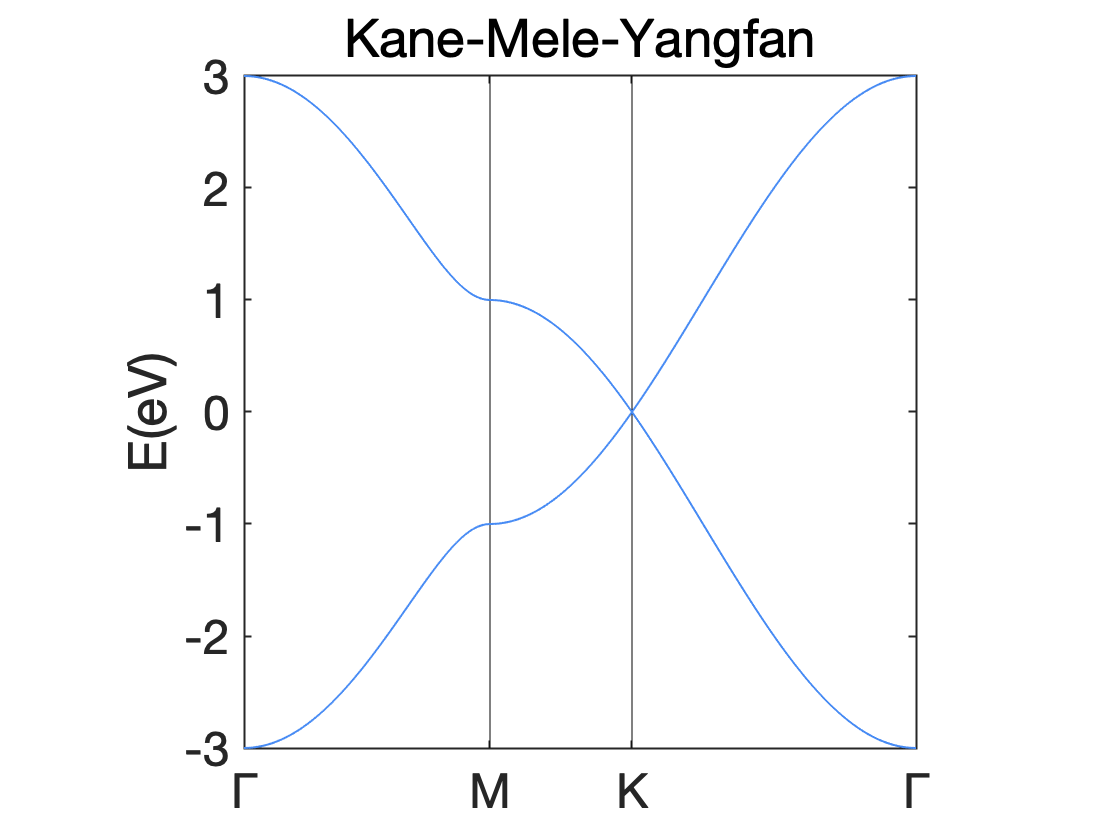

bandplot(EIGENCAR ,[-3,3]);

### 输出hr.dat

Graphene_n.Gen_hr();% Graphene_n.Gen_hr('wannier90_hr.dat');

Wrinting (1/5)  NRPT
Wrinting (2/5)  NRPT
Wrinting (3/5)  NRPT
Wrinting (4/5)  NRPT
Wrinting (5/5)  NRPT


## Kane-Model model

我们知道，K-M model 是包含虚数的次近邻跃迁项的，但我们上一节中构造的TB却只有最近邻，是否能一步到位将次近邻也构造出来呢？

HRclass的数据存储逻辑基于 wannier90_hr.dat 格式，在赋值后，我们可以将数据导出到本地查看

% Graphene_n.Gen_hr('wannier90_hr.dat')
% Graphene.vectorL

可以看出，从 i 到 j 和从 j 到 i 这样一对共轭跃迁项，在数据格式上并没有直接的联系，所以我们也无法将它们的取值直接赋值成复共轭的形式。所以我们需要将上一节得到的TB模型做直和，以手动加倍wannier基底至自旋空间，然后引入虚数次近邻项。这里，既可以单独为每一个跃迁赋值，也可以直接传入一个2阶矩阵。set_hop就会自动把4个矩阵元分配到 i-site 自旋上下向 j-site 自旋上下这一组四个跃迁中。

V_NNN = [1 0 0; 0 1 0; -1 -1 0];
lambda_SO = 0.1 * VppP_1;

Kane_Mele = [Graphene,Graphene];
Kane_Mele = Kane_Mele.set_hop(...
     kron(sigma_z, -1i*lambda_SO),1,1,V_NNN,'sym');
Kane_Mele = Kane_Mele.set_hop(...
     kron(sigma_z,  1i*lambda_SO),2,2,V_NNN,'sym');

Kane_Mele = Kane_Mele.autohermi()

For sym Hr, The requirement is strick!The sym vasiable is real or in the original Hr, use conj()check 1 th : NRPT,
 the vector is -1 0 0,
 the opposite vector is 1,0,0 the 5 th NRPT
The opposite vector hamilton is not hermi, replace it by strong mat! 
The 5 th NRPT is stonger!


$$\left(\begin{array}{cccc} \frac{1}{10}\,\mathrm{i} & {\mathrm{VppP}}_{1} & 0 & 0\\ 0 & -\frac{1}{10}\,\mathrm{i} & 0 & 0\\ 0 & 0 & -\frac{1}{10}\,\mathrm{i} & {\mathrm{VppP}}_{1}\\ 0 & 0 & 0 & \frac{1}{10}\,\mathrm{i} \end{array}\right)$$

check 2 th : NRPT,
 the vector is 0 -1 0,
 the opposite vector is 0,1,0 the 4 th NRPT
The opposite vector hamilton is not hermi, replace it by strong mat! 
The 4 th NRPT is stonger!


$$\left(\begin{array}{cccc} \frac{1}{10}\,\mathrm{i} & 0 & 0 & 0\\ {\mathrm{VppP}}_{1} & -\frac{1}{10}\,\mathrm{i} & 0 & 0\\ 0 & 0 & -\frac{1}{10}\,\mathrm{i} & 0\\ 0 & 0 & {\mathrm{VppP}}_{1} & \frac{1}{10}\,\mathrm{i} \end{array}\right)$$

check 3 th : NRPT,
 the vector is 0 0 0,
 the opposite vector is 0,0,0 the 3 th NRPT
check 4 th : NRPT,
 the vector is 0 1 0,
 the opposite vector is 0,-1,0 the 2 th NRPT
hermi test pasts
check 5 th : NRPT,
 the vector is 1 0 0,
 the opposite vector is -1,0,0 the 1 th NRPT
hermi test pasts
check 6 th : NRPT,
 the vector is -1 -1 0,
 the opposite vector is 1,1,0 the 0 th NRPT
The opposite vector hamilton is not exist, build it!


$$\left(\begin{array}{cccc} \frac{1}{10}\,\mathrm{i} & 0 & 0 & 0\\ 0 & -\frac{1}{10}\,\mathrm{i} & 0 & 0\\ 0 & 0 & -\frac{1}{10}\,\mathrm{i} & 0\\ 0 & 0 & 0 & \frac{1}{10}\,\mathrm{i} \end{array}\right)$$

Kane_Mele =   HR - 属性:

        vectorL: [7×3 int32]
          HnumL: [4×4×5 double]
          HcoeL: [4×4×7 sym]
          NRPTS: 7
        WAN_NUM: 4
       Line_000: 3
      Basis_num: 2
             Rm: [3×3 double]
             Gk: [3×3 double]
    symvar_list: [1×1 sym]


Kane_Mele_n = Kane_Mele.Subsall();
EIGENCAR = Kane_Mele_n.EIGENCAR_gen();

BAND caculating 180/180 ...


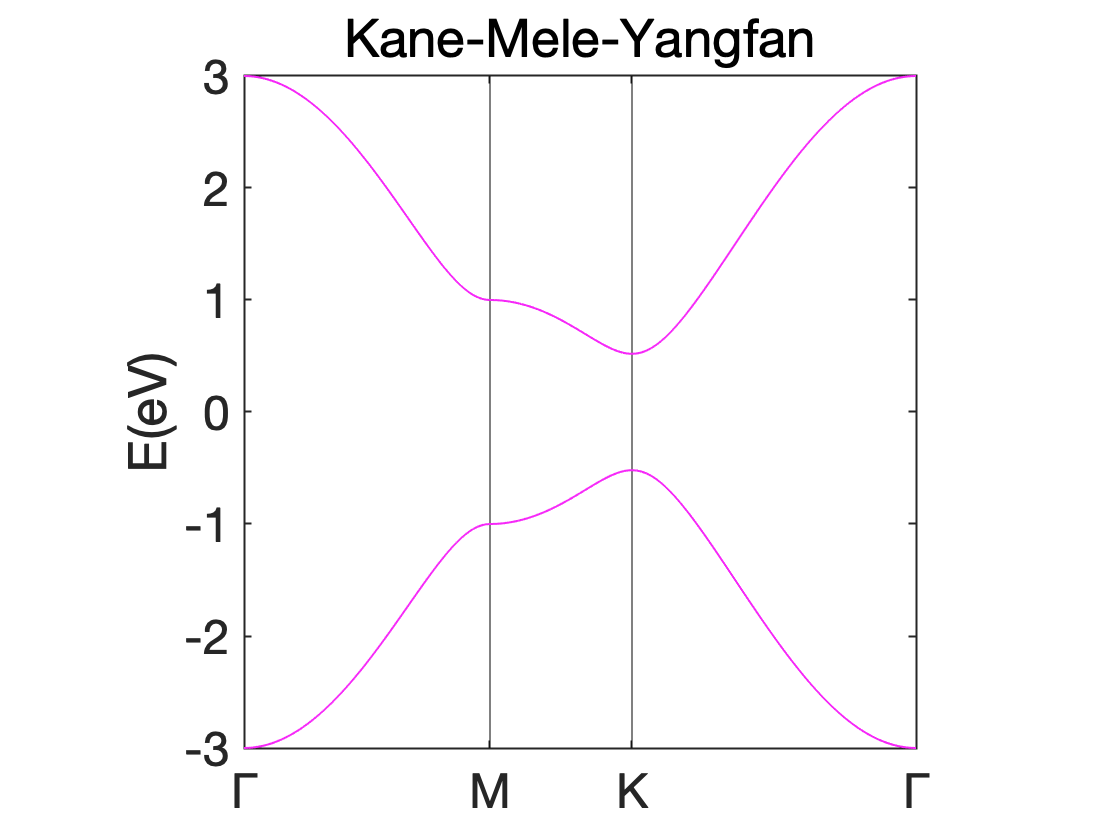

bandplot(EIGENCAR ,[-3,3]);

## Zeeman field

Kane-Mele model加磁场的效应，相当于同一site上不同自旋态间的跃迁，所以这里原胞跃迁矢量就只有 [0 0 0] 项。

Lambda = 0.2 * VppP_1;
B_x = 0.0;
B_y = 1;
B_z = 0;
B_dot_s = B_x*sigma_x + B_y*sigma_y + B_z*sigma_z;
Kane_Mele_Mag = Kane_Mele;
Kane_Mele_Mag = Kane_Mele_Mag.set_hop(...
    kron(B_dot_s,Lambda),1,1,[0,0,0],'sym');
Kane_Mele_Mag = Kane_Mele_Mag.set_hop(...
    kron(B_dot_s,Lambda),2,2,[0,0,0],'sym');

Kane_Mele_Mag_n = Kane_Mele_Mag.Subsall();
EIGENCAR = Kane_Mele_Mag_n.EIGENCAR_gen();

BAND caculating 180/180 ...


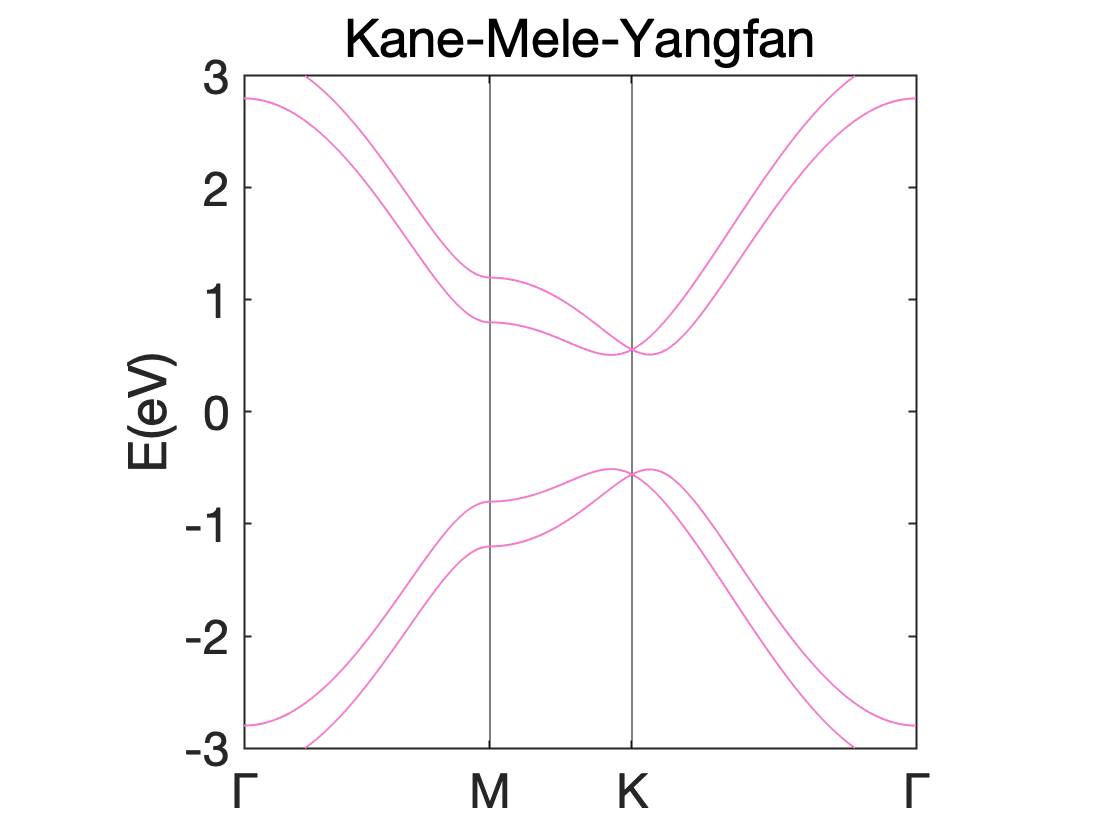

bandplot(EIGENCAR ,[-3,3]);

## 能级与角落态

最后，我们将展现Kane-Mele加磁场模型的物理意义。设置Nslab，将石墨烯原胞扩展为一个纳米盘 (nanodisk / nanoflake)。我们不再使用能带绘图功能，而是直接按能量大小排列出所有本征态，就可以发现在费米面附近的两个近似简并的零能态。使用matlab图像的交互功能，我们直接点击这两个点就可以查看它们在OUTPUT中的序号，单独绘制它们波函数的分布，就可以发现其集中于纳米盘的角落。也就是说，体绝缘的石墨烯纳米盘结构，在外加Y方向的磁场后，出现了导电的角落态 (corner state)。

Nslab = [20 20 1];
np = 1;
vacuum_mode = 1;
% Gen disk-
n_disk = Kane_Mele_Mag_n.Hnanowire_gen(Nslab,np,vacuum_mode);

Gen (1/1) NRPT z 
1 th NRPT z ---- Gen (1/3) NRPT y 
Gen NRPT x: 2/2
1 th NRPT z ---- Gen (2/3) NRPT y 
Gen NRPT x: 

[EIGENCAR_disk,WAVECAR_disk] = n_disk.EIGENCAR_gen('klist',[0 0 0],'norb',-1,'fermi',0);
figure();
plot(EIGENCAR_disk,'-o');
ylim([-1 1]);

WaveFunc = WAVECAR_disk(:,800:801);
orb_list = n_disk.orbL;
figure();
PARCHG_gen(orb_list,WaveFunc*3);
axis equal
view(0,90)

## 参考文献

DOI: 10.1103/PhysRevLett.124.166804 